# Simulation Study on Manifolds with the Ground Truth

%
% (C) 2019- Moo K. Chung
% University of Wisconsin-Madison
% mkchung@wisc.edu
%
% The script is based on the simulation study given in
%
% Chung, M.K., Qiu, A., Seo S. Vorperian, H.K. 2015. Unified heat kernel regression for 
% diffusion, kernel smoothing and wavelets on manifolds and its application to mandible growth 
% modeling in CT images, Medical Image Analysis. 22:63-76,  arXiv:1409.6498 
%
% The code is downloaded from
% https://github.com/laplcebeltrami/lb
%
% Update histroy:
% Created 2019 March 06 modified from
% SIMULATION3-sigma2.2019.03-bookchapter.m
% Updated 2024 March 01




## Loading Manifold

% load T-junction and compute LB-eigenfunctions
load Tjunc1
tt = isosurface(Tjunc1)

tt = struct with fields:
    vertices: [1930×3 double]
       faces: [3856×3 double]


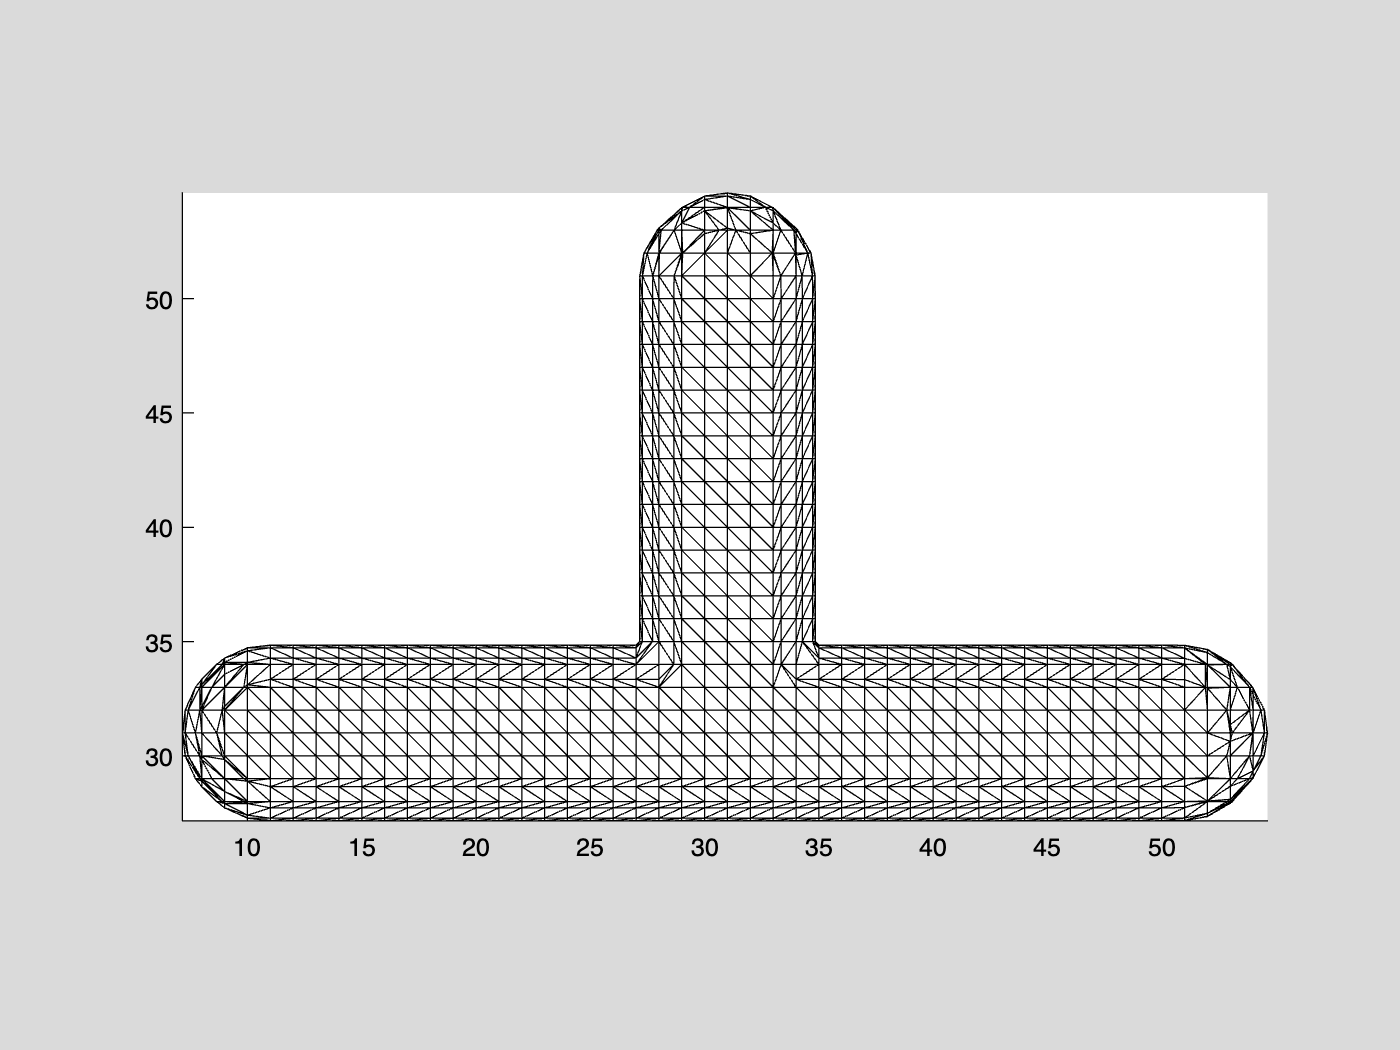

figure; figure_wire(tt); 

## Marking the location of ground truth

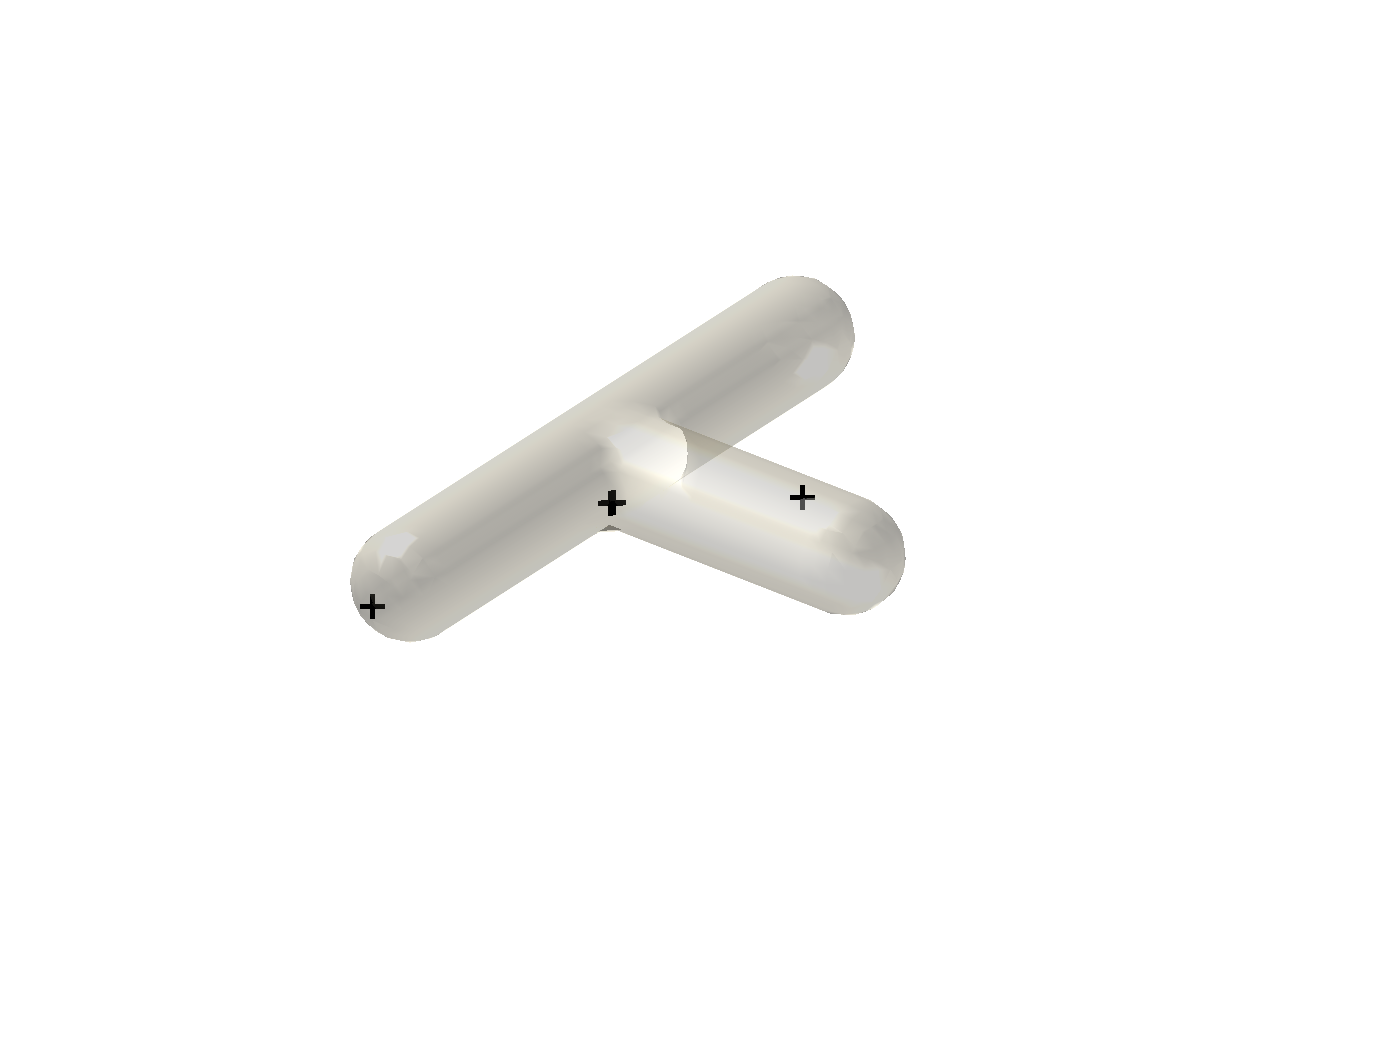

% Identiy 3 diffrent regions and assign value 1 as signal and 0 everywhere. 
% These are manually identified to have diffenret local metric structure or
% curvature

node=tt.vertices;
vector2=[35 35 31];
diff=L2norm(node, vector2);
node1 = find(diff==min(diff));

vector2=[55 31 31];
diff=L2norm(node, vector2);
node2 = find(diff==min(diff));

vector3=[32 48 35];
diff=L2norm(node, vector3);
node3 = find(diff==min(diff));

figure; figure_patch(tt,[0.74 0.71 0.61],0.3);
hold on; plot3(node(node1,1),node(node1,2),node(node1,3),'+k', 'MarkerSize',10,'LineWidth', 2);
hold on; plot3(node(node2,1),node(node2,2),node(node2,3),'+k','MarkerSize',10, 'LineWidth', 2);
hold on; plot3(node(node3,1),node(node3,2),node(node3,3),'+k','MarkerSize',10, 'LineWidth', 2);
camlight; view([128 30])

## Building Group I ground truth: No signal

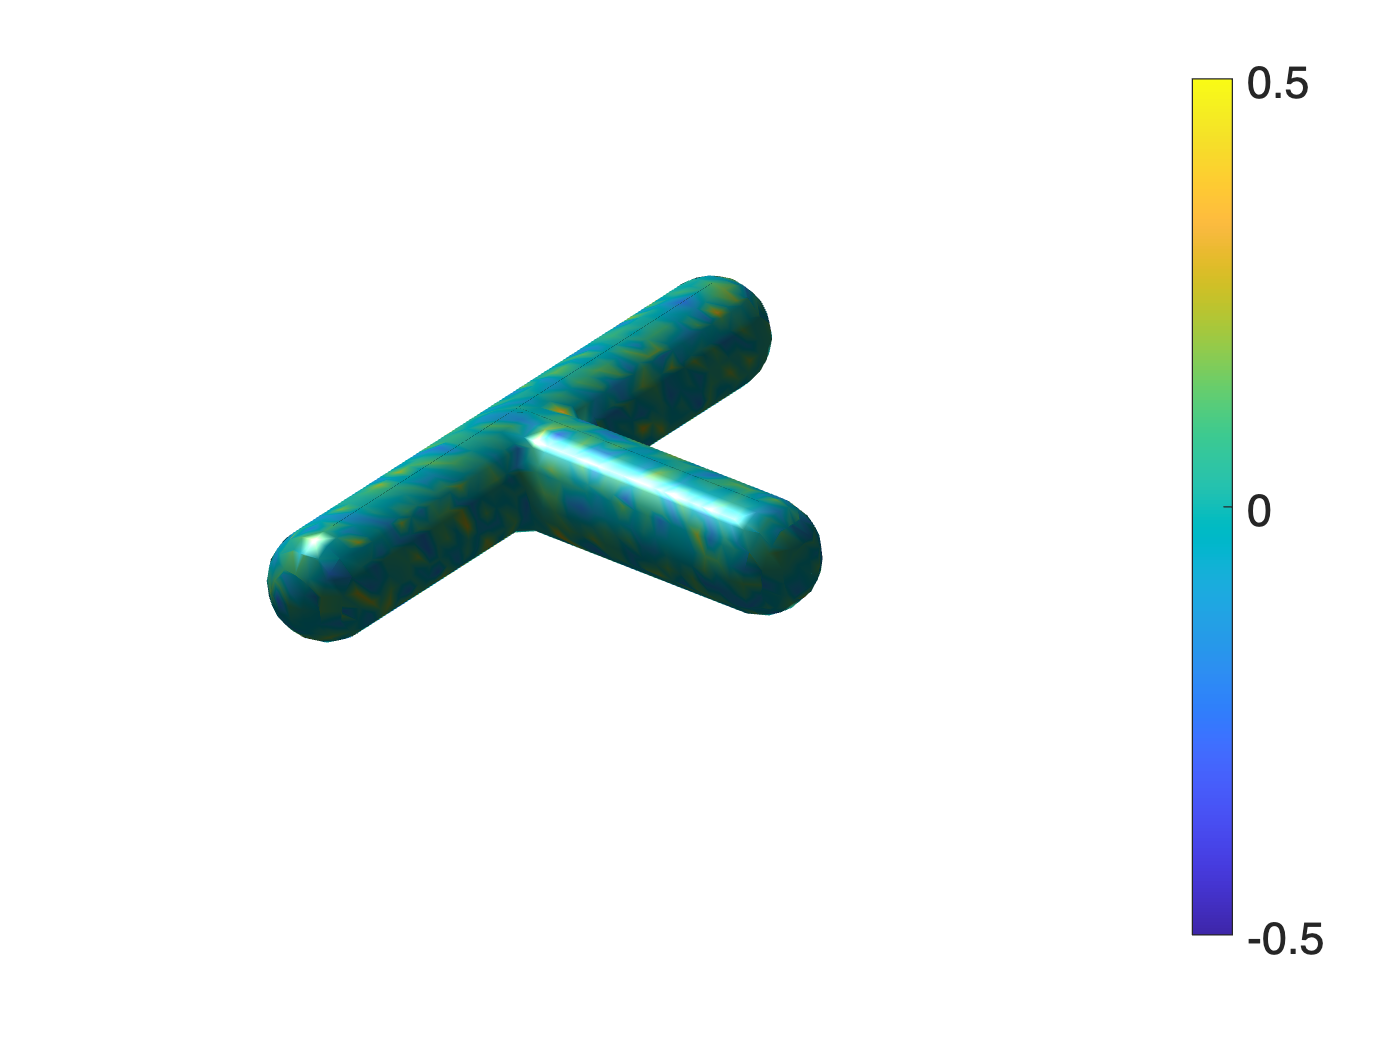

%Generating the simulated random data with the ground truth
%Random noise everywhere.
nv=size(node,1); %number of nodes
nosignal = normrnd(0,0.1, nv,1);; %There is no signal
figure; figure_surf(tt, nosignal); colorbar; clim([-0.5 0.5]);  camlight
view([128 30]); figure_bigger(20)

## Building Group II ground truth: Signal

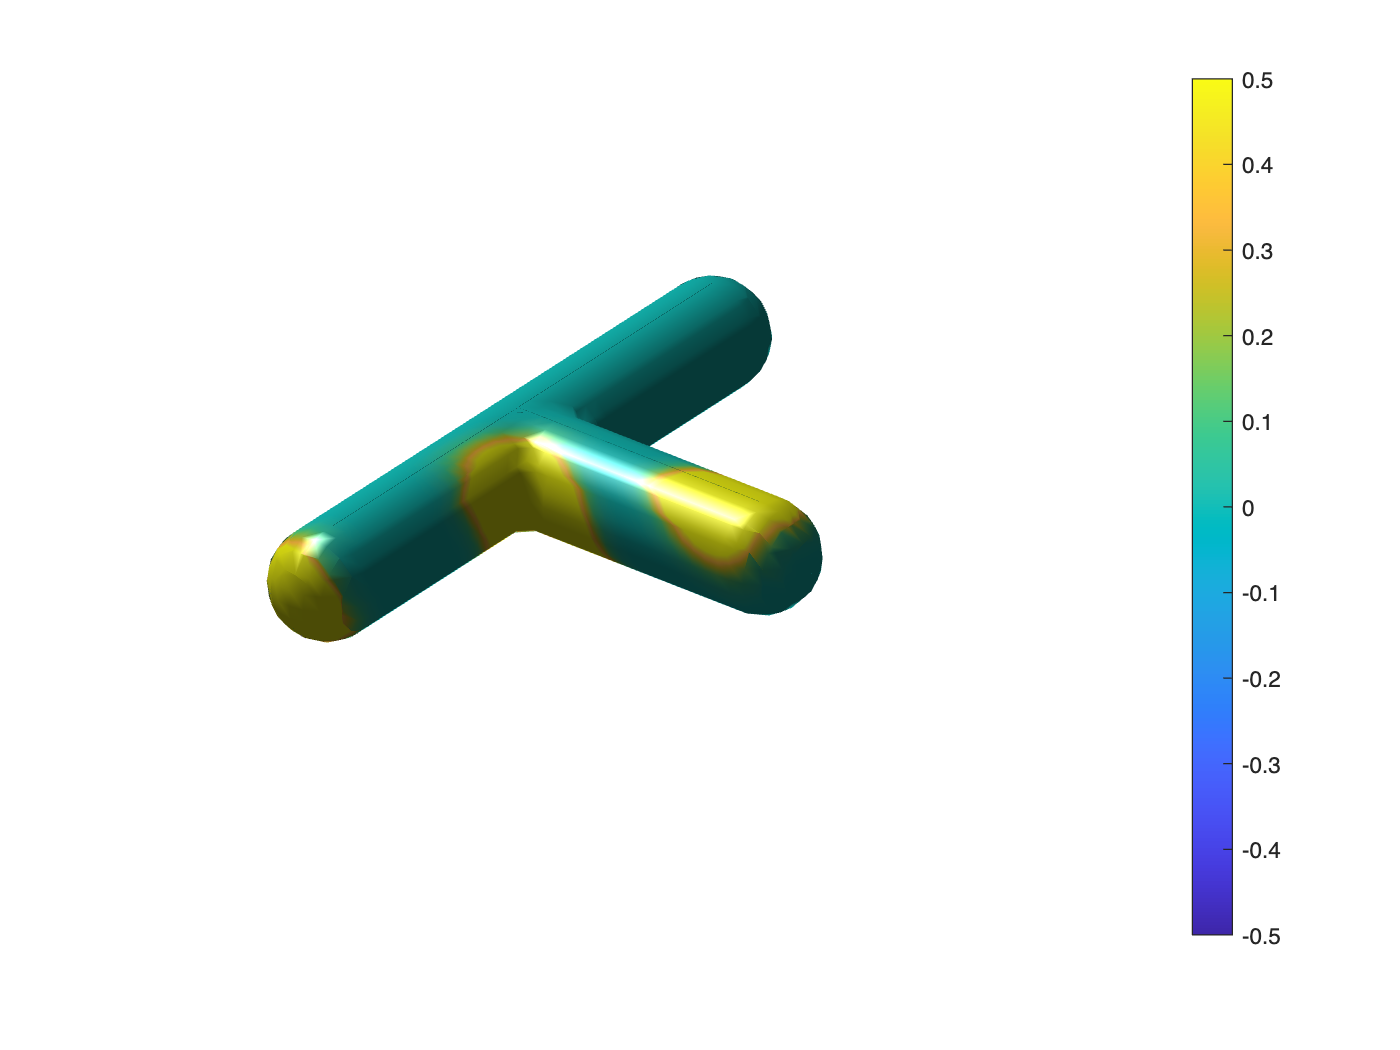

% We will assign value 1 to areas around node1, node2 and node3, and 0 % everywhere. 
% We will call those areas as area1, area2, area3. 

%Assign value 10 to 3 
signal = zeros( nv,1);
signal(node1)=100;
signal(node2)=100;
signal(node3)=100;

signal=hk_smooth2(signal,tt, 100, 10); %perform heat kernel smoothing with 100 iterations and bandwidth 10
figure; figure_surf(tt, signal); clim([-0.5 0.5]); colorbar; camlight
view([128 30]); 

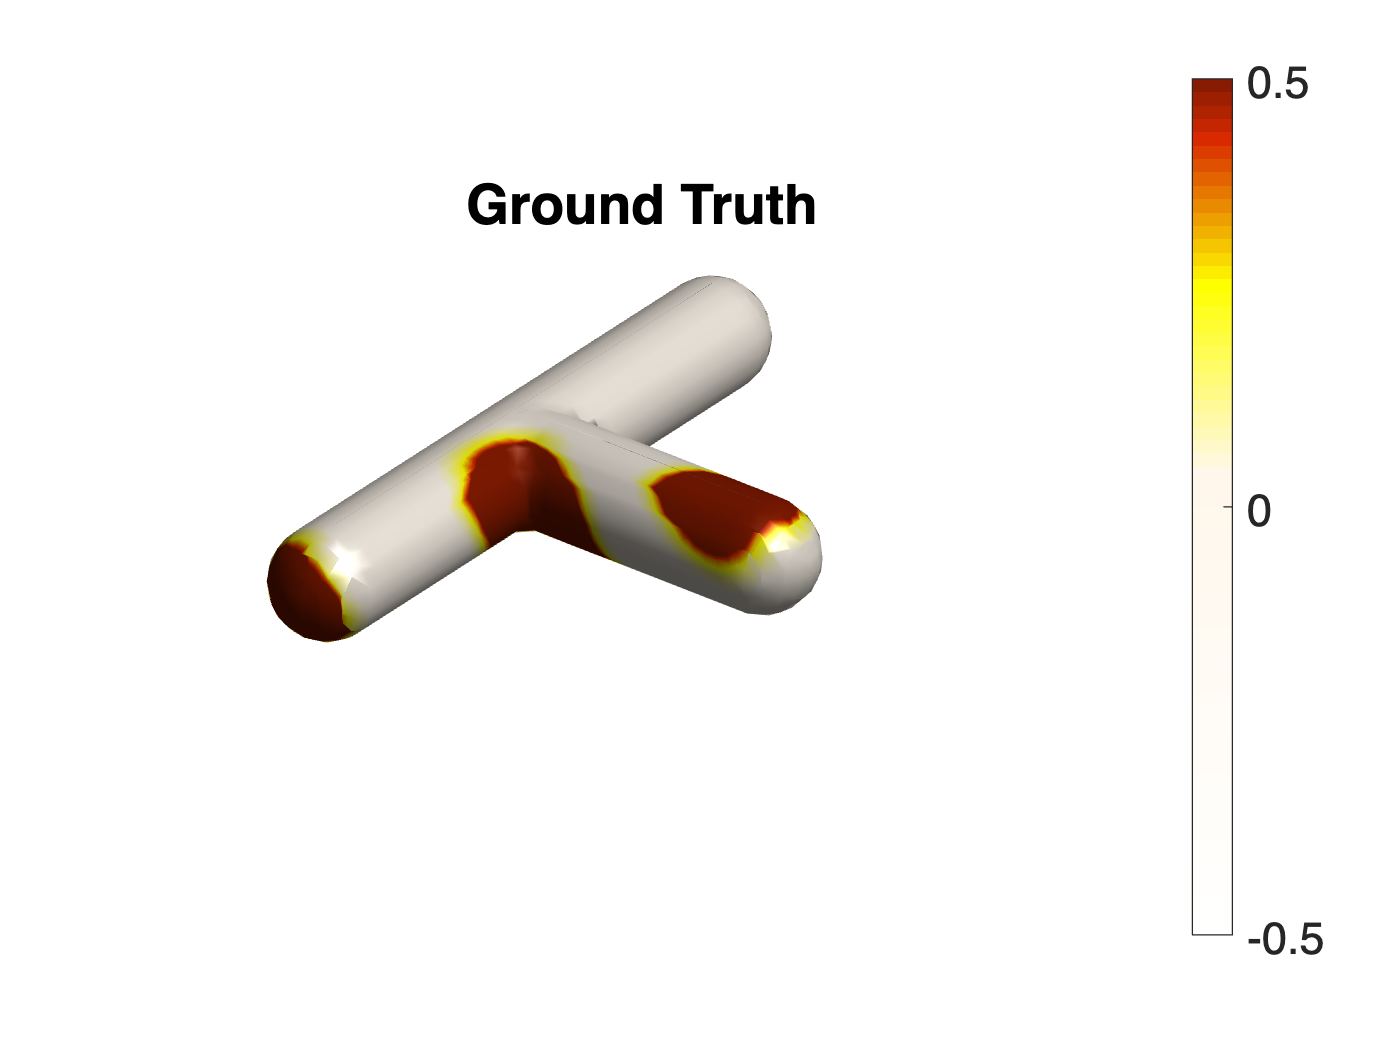

%We threshold signal and make it binary. The ground truth is 1 in area1, area2, area3 and 0 everywhere.
%This simpliestic binary image on manifold is the grond truth. 

%region of interest (ROI) defining signal
ROI=find(signal>0); %signal region. You should detect this area
ROIN=find(signal==0); %nonsignal region. You should not detect this area

%Ground truth for group I
figure; figure_surf(tt, signal, 'ryw'); %This binary image is our ground truth. 
clim([-0.5 0.5]); colorbar; view([128 30])
camlight;figure_bigger(20); title('Ground Truth')

## Statitical Simiulation with the Ground Truth 

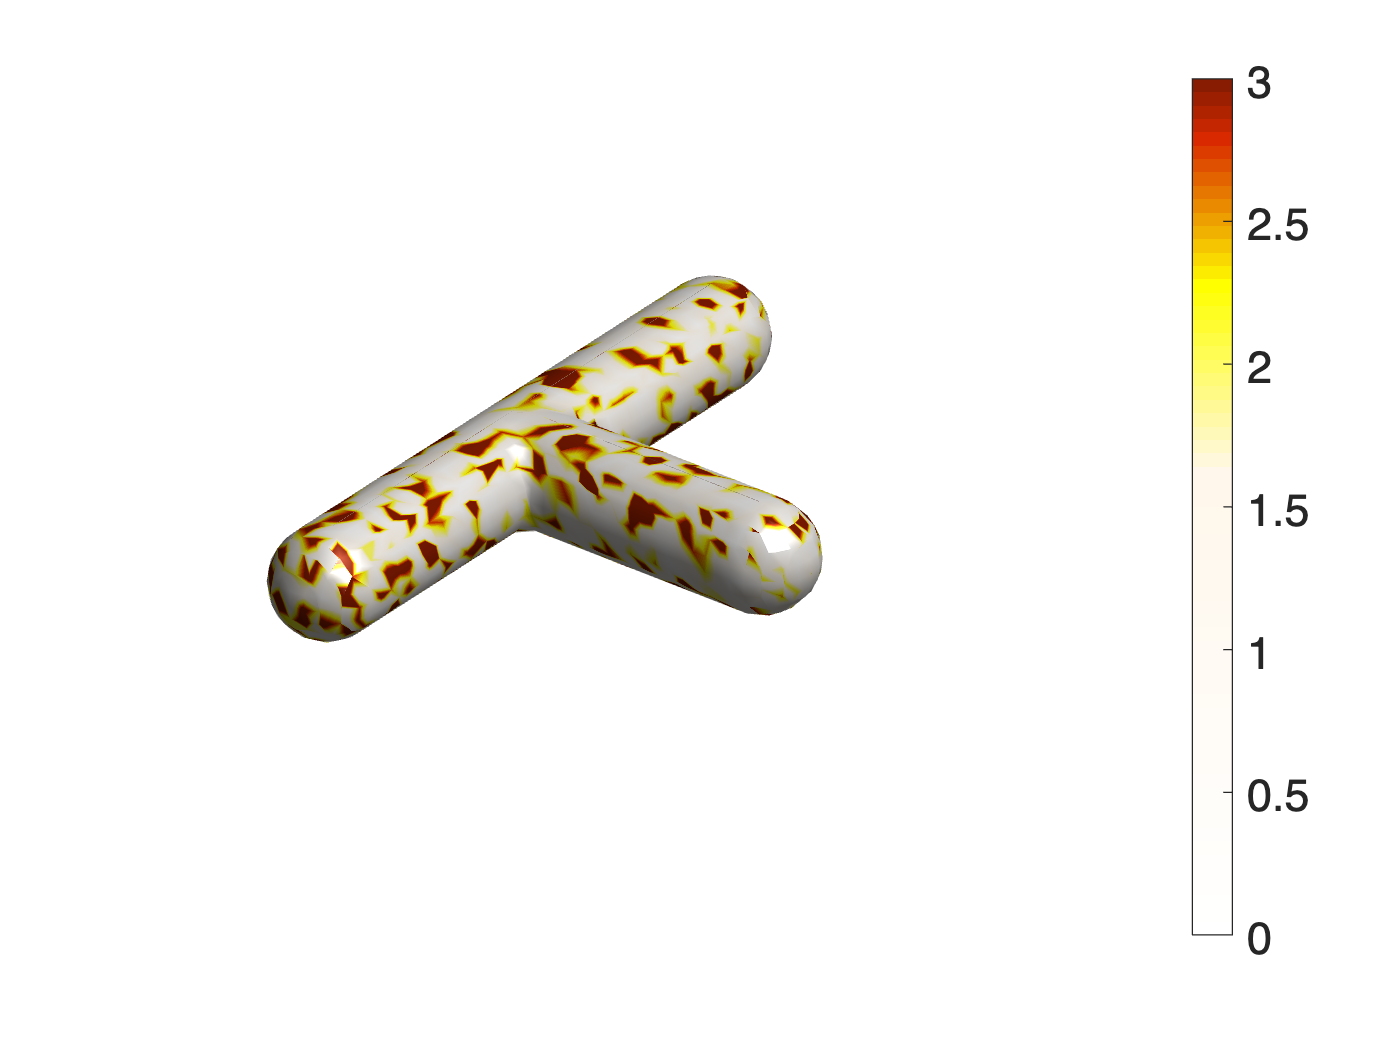

%We will simulate 30 subjects and 30 subjects in each group.

% Simulated 30 subjects in Group I
measure= zeros(60,nv);
for i=1:30
    measure(i,:) = (abs(normrnd(0,2, nv,1)))';
end;
%measure(1:30,:) has no signal

% Simulated 30 subjects in Group II
for i=31:60
    measure(i,:) = (signal + abs(normrnd(0,2, nv,1)))';
end;
%measure(31:60,:) has signal

measure1=measure(1:30,:); %no signal
measure2=measure(31:60,:); %signal

%One subject from group I
figure; figure_surf(tt, measure1(1,:),'ryw');; colorbar
view([128 30])
material metal
camlight; camlight
figure_bigger(20)
caxis([0 3])

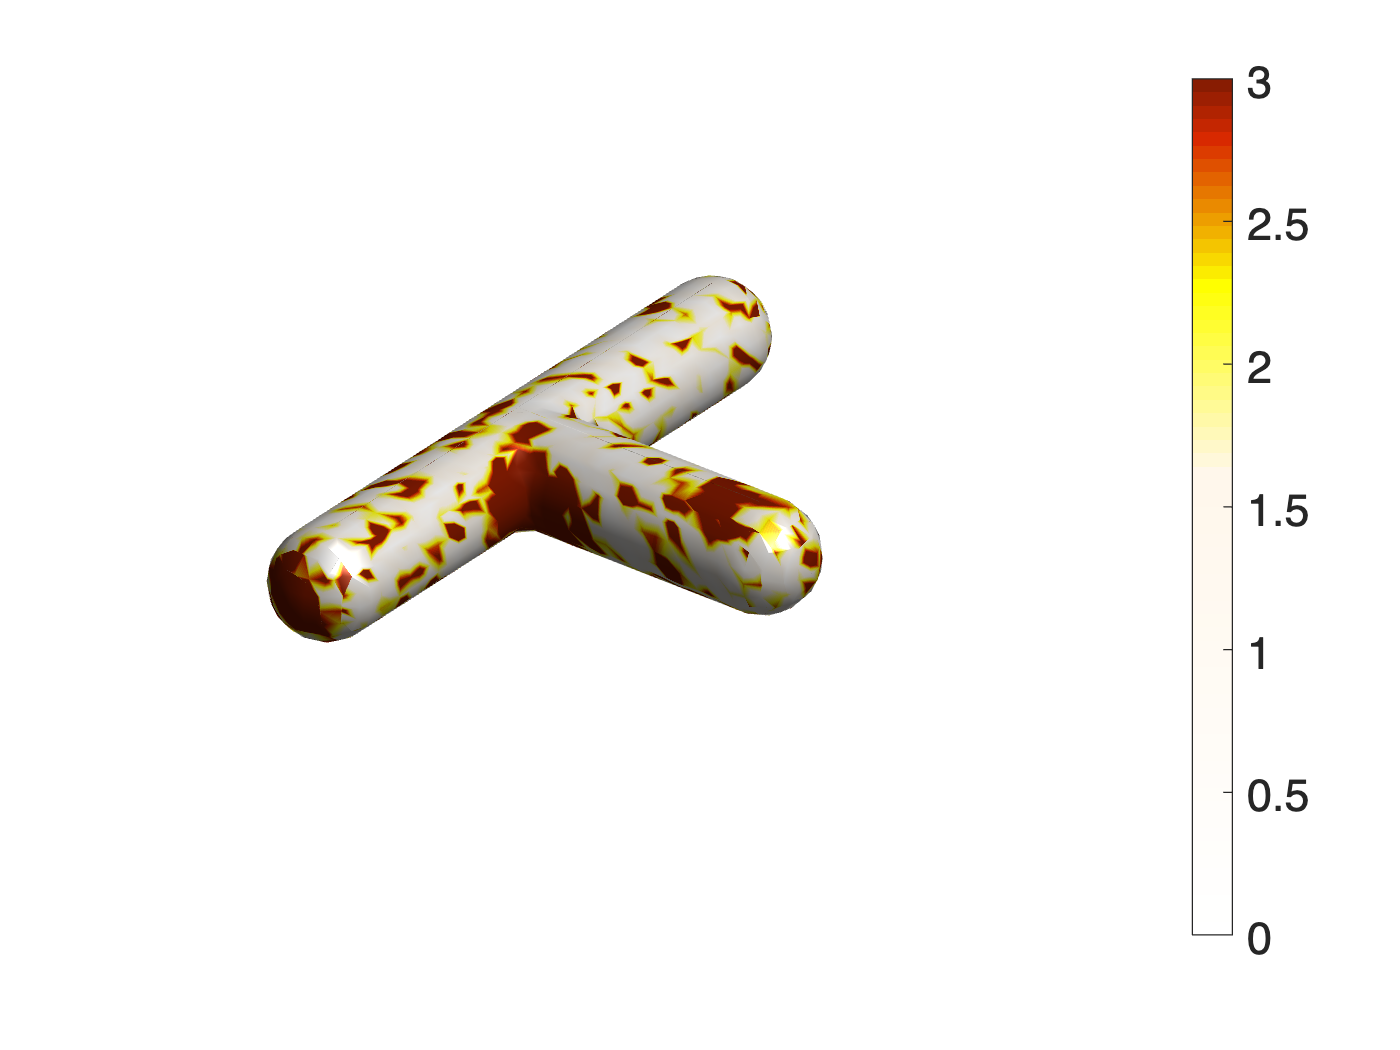

%One subject from group II
figure; figure_surf(tt, measure2(1,:),'ryw');; colorbar
view([128 30])
material metal
camlight; camlight
figure_bigger(20)
caxis([0 3])

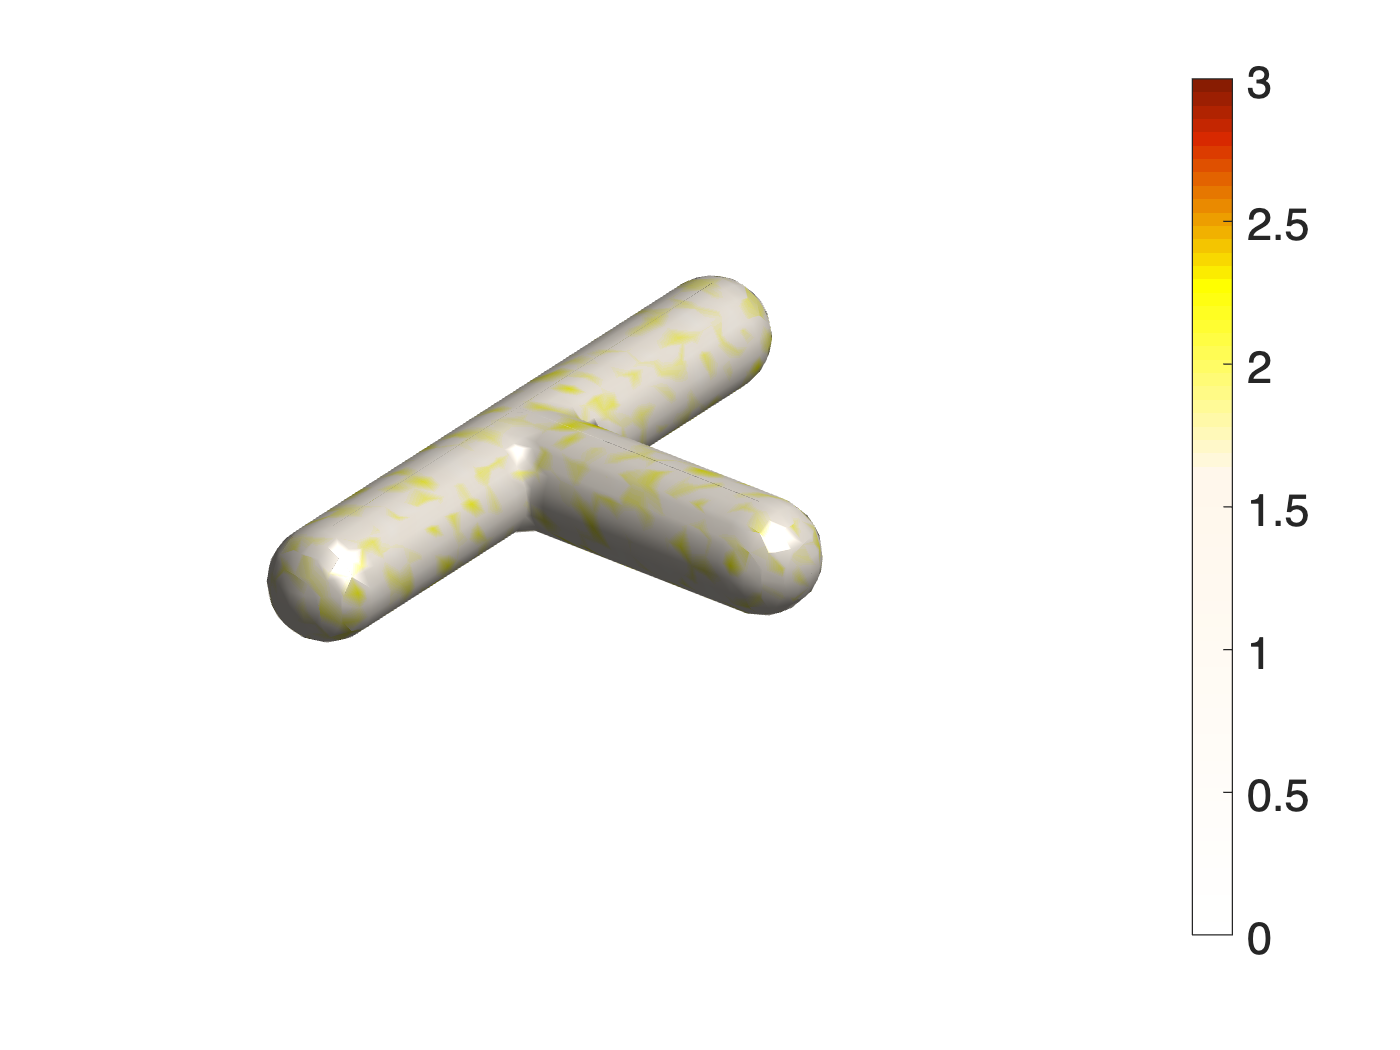

%Average of group I
figure; figure_surf(tt, mean(measure1,1),'ryw'); colorbar
view([128 30])
material metal
camlight; camlight
figure_bigger(20)
caxis([0 3])

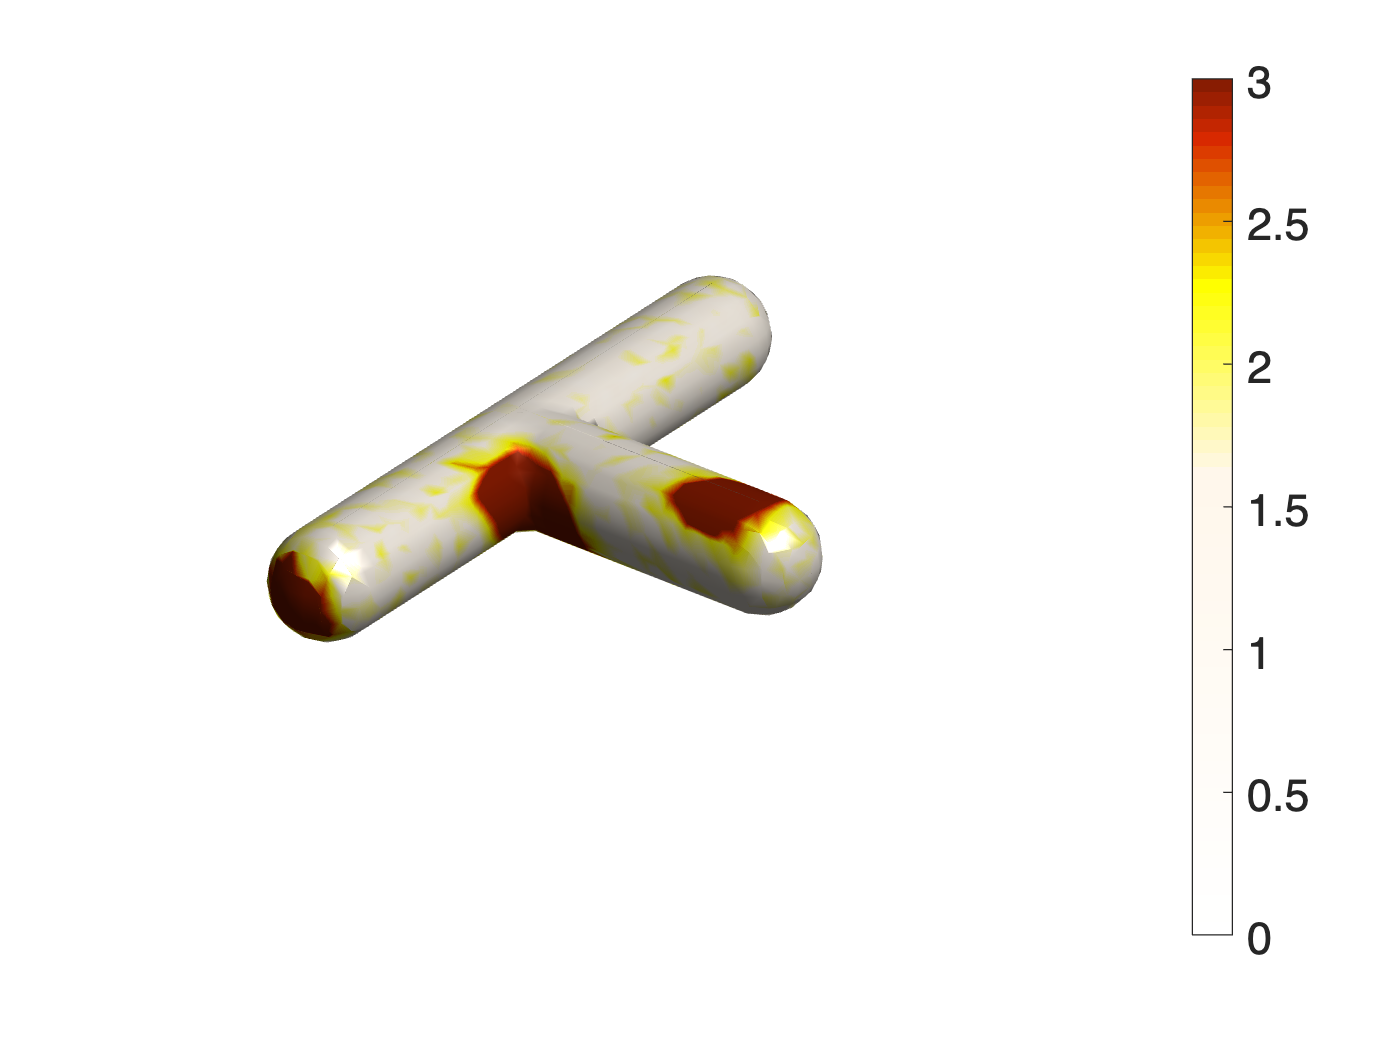

%Average of group II
figure; figure_surf(tt, mean(measure2,1),'ryw'); colorbar
view([128 30])
material metal
camlight; camlight
figure_bigger(20)
caxis([0 3]) 

%This is why avearging is such a powerful tool. You detect sginal by simply averaging most of time. 
%But this is averging in Group II. How to integrate data in Group I as
%well? Through two-sample t-statistic.

## Two Sample t-test on Original noise Data

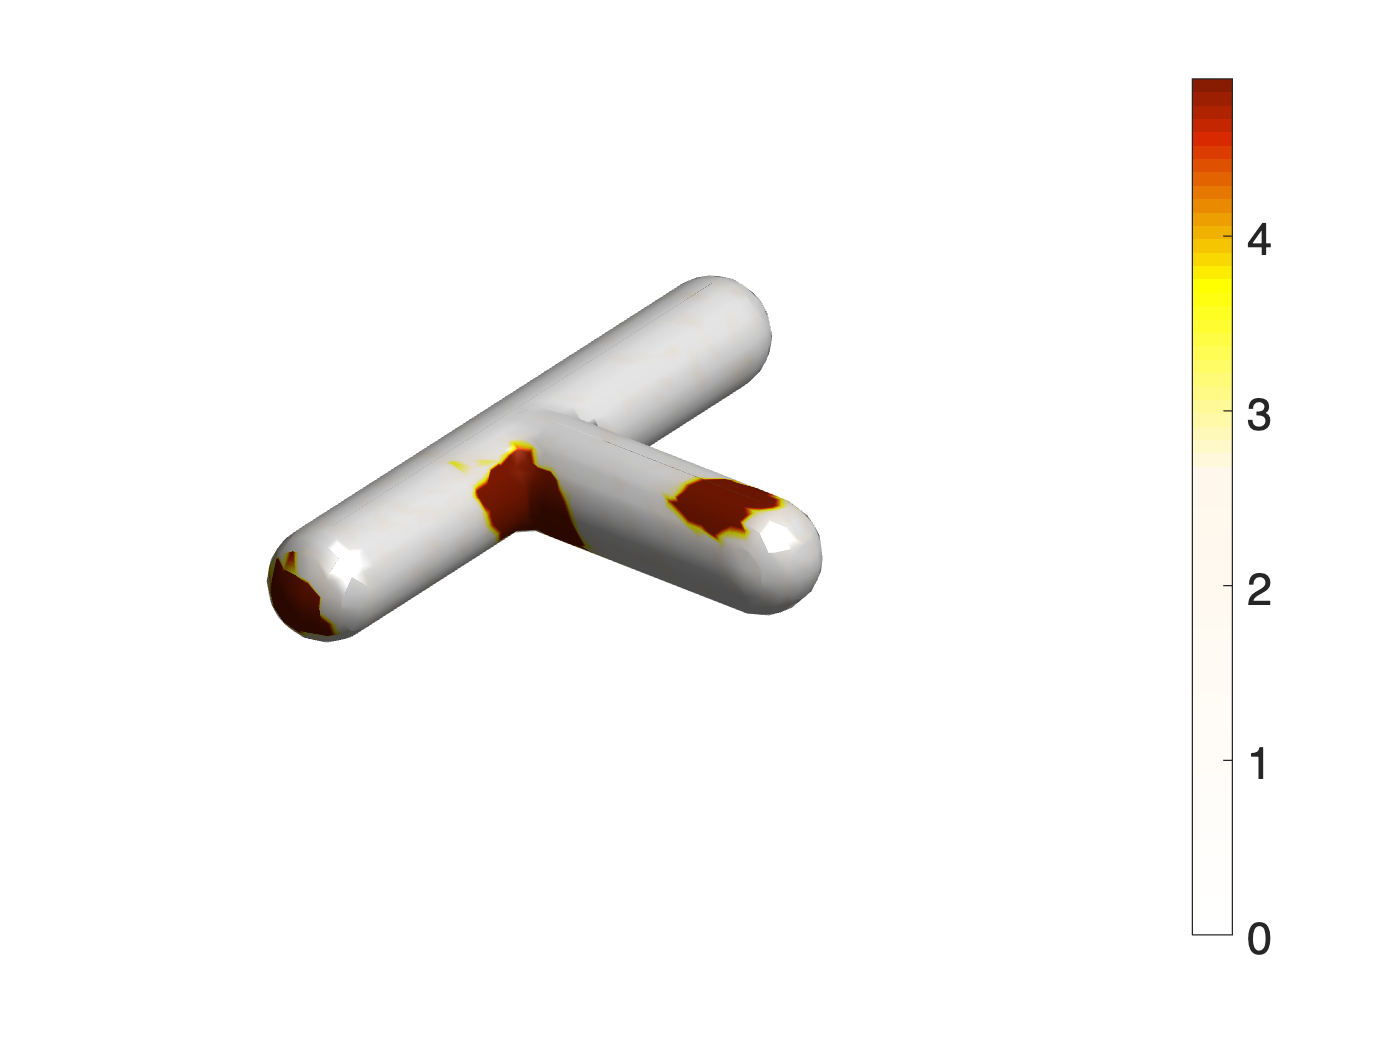

% For performandce analysis, we need to threshold t-stat map somewhere. The thresholded map is signal. 

% a=1; b=60 -2;
% %F.tstat=[34.4 34.5 34.6 35 40]
% F.tstat=[24 24.5 25]
% F.df=[a b]
% sigma=0.5;
% pvalue=stat_Fcorrected(F, sigma,Tjunc1)
% thd= sqrt(24)   
% %5.87 for sigma= 0.1
% %4.90 for sigma = 0.5

%We will use the threshold 4.9 determined by the random field theory. Read
%the paper to undersatnd the mathemtical tehroy behond why 4.9 is chosen. 

thd = 4.9;

% Performance analayis of t-stat on original data
tfield=[];
for i=1:nv
[h p, ci, t] = ttest2(measure2(:,i), measure1(:,i),[],[],'equal');
tfield=[tfield t.tstat];
end;

figure; figure_surf(tt, tfield,'ryw'); colorbar
view([128 30])
material metal
camlight; camlight
figure_bigger(20)
caxis([0 thd])  

%Quantification.

overlap1 = find(tfield(ROI)>=thd);
length(overlap1)/length(ROI)

ans = 0.0998

%1%-10% of signal is detected in area 1, area2, area3. The performance is
%terrible. The false neative error rate (FNE) is 1- length(overlap1)/length(ROI).

%False positive
overlap1 = find(tfield(ROIN)>=thd);
length(overlap1)/length(ROI)

ans = 0

% This should be around 0% - 1%   No signal is deteceted. So false positive error rate  (FPE)is 0%.


## Two Sample t-test on Iterated Heat Kernel Smoothing

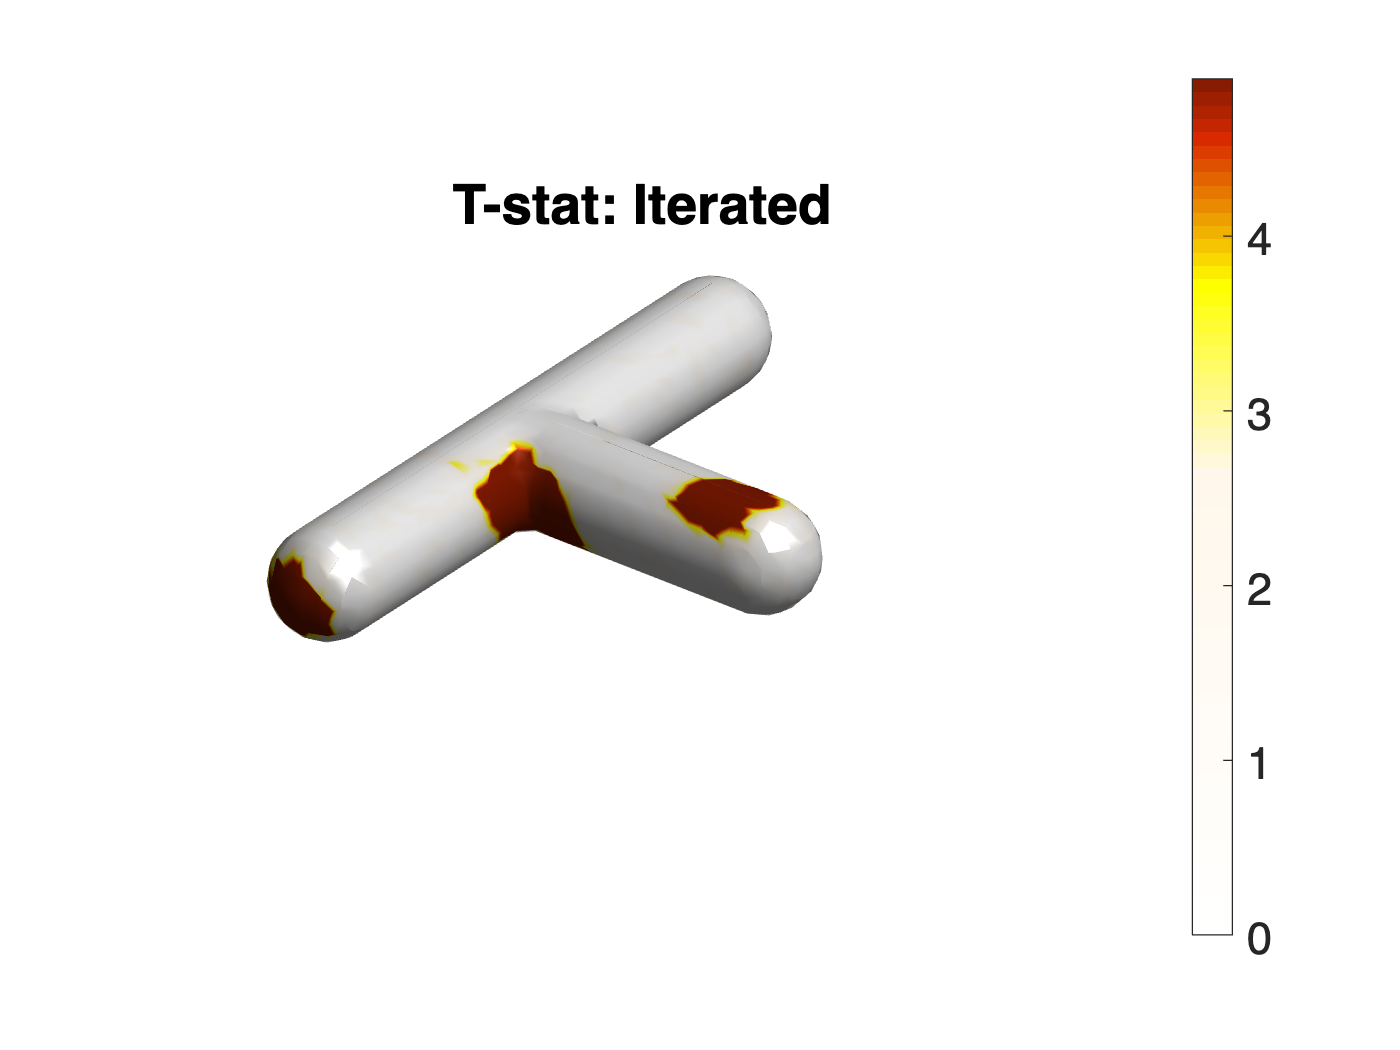

m=100;  %number of iterations 
dsigma=0.5/m;  %the small bandwith. Total bandwidth is m*dsigma = 0.5 = amount of diffusion
hkresults=hk_smooth2(measure',tt, dsigma, m);

hkresults1=hkresults(:,1:30);
hkresults2=hkresults(:,31:60);

tfield=[];
for i=1:nv
[h p, ci, t] = ttest2(hkresults2(i,:), hkresults1(i,:),[],[],'equal');
tfield=[tfield t.tstat];
end;

figure; figure_surf(tt, tfield,'ryw'); colorbar
view([128 30])
material metal
camlight; camlight
figure_bigger(20)
title('T-stat: Iterated')
caxis([0 thd])


overlap1 = find(tfield(ROI)>=thd);
length(overlap1)/length(ROI);
% 0.0312
overlap1 = find(tfield(ROIN)>=thd);
length(overlap1)/length(ROI);

## Two Sample t-test on Heat kernel smoothing with LB-egenfunction expansion

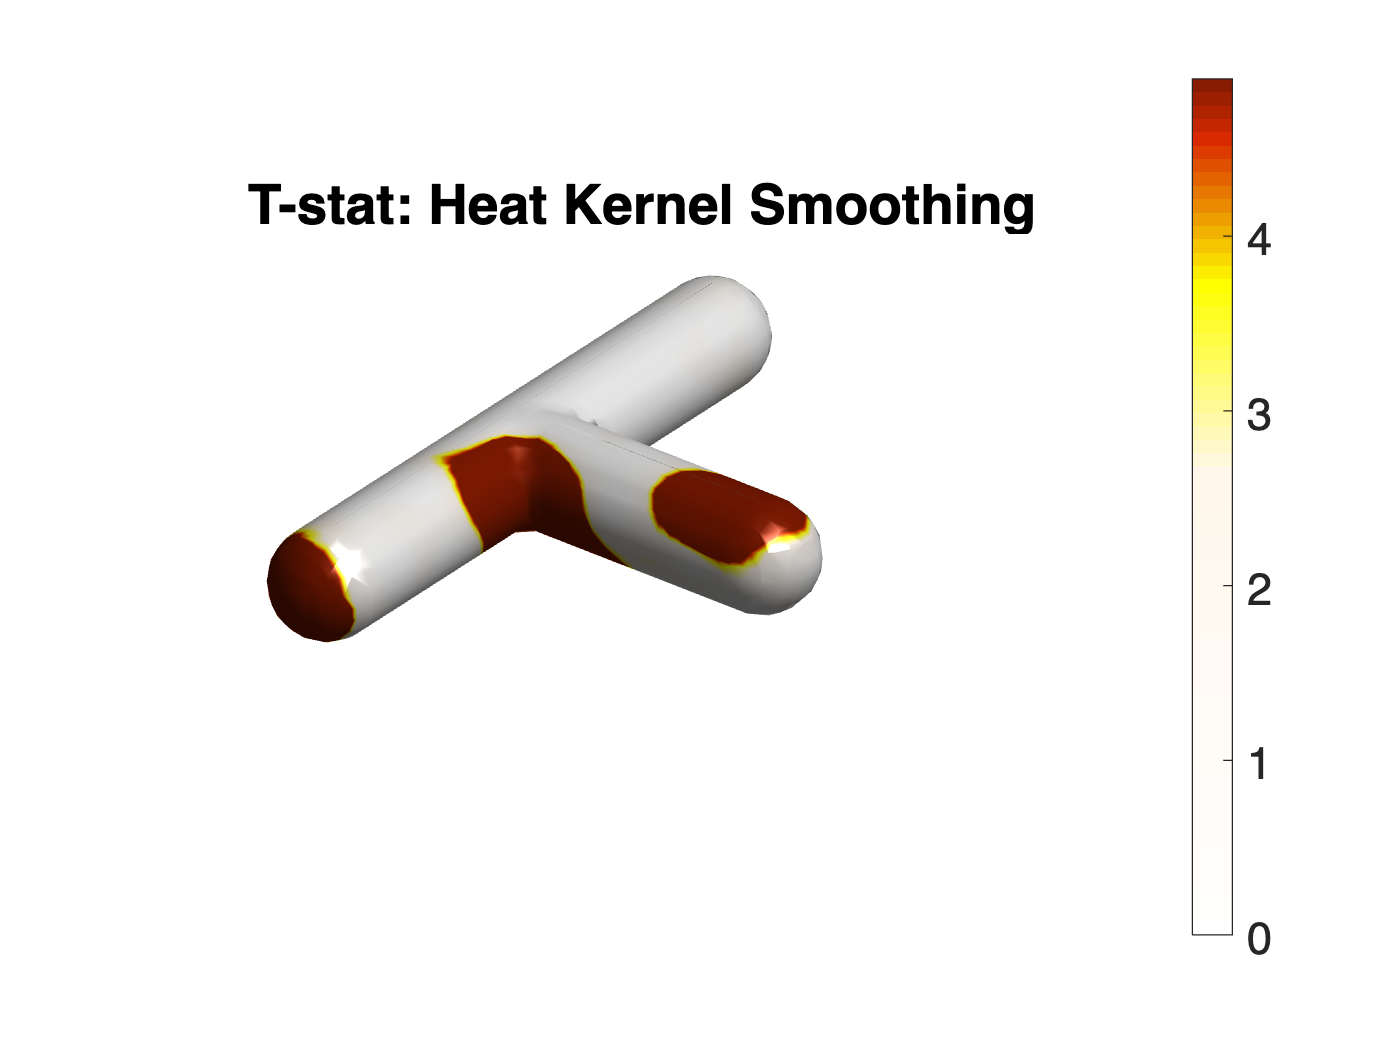

%Smoothing will boost signal dramatically.
%We will perform heat kernel smoothing with m=100 iteratiosn and kernel bandwith 0.005
%Eigenfunctions are estimated using FEM 

[A, C]= FEM(tt); %setting up FEM
[V, D]= eigs(C,A, 1000,'sa'); %Generalized eigenvalue problem for finding eigenvectors
msmooth=lb_smooth(measure',tt, 0.5, 1000, V, D);

mresults1=msmooth(:,1:30);
mresults2=msmooth(:,31:60);

tfield=[];
for i=1:nv
[h p, ci, t] = ttest2(mresults2(i,:), mresults1(i,:),[],[],'equal');
tfield=[tfield t.tstat];
end;

figure; figure_surf(tt, tfield,'ryw'); colorbar
view([128 30])
material metal
camlight; camlight
figure_bigger(20)
title('T-stat: Heat Kernel Smoothing')
caxis([0 thd])


overlap1 = find(tfield(ROI)>=thd);
length(overlap1)/length(ROI)

ans = 0.2952

% It will give the best performance with the smallest false negative error
% rate.
overlap1 = find(tfield(ROIN)>=thd);
length(overlap1)/length(ROIN)

ans = 0

% 0.0011

## LB-eigenfunction Method on Manifold

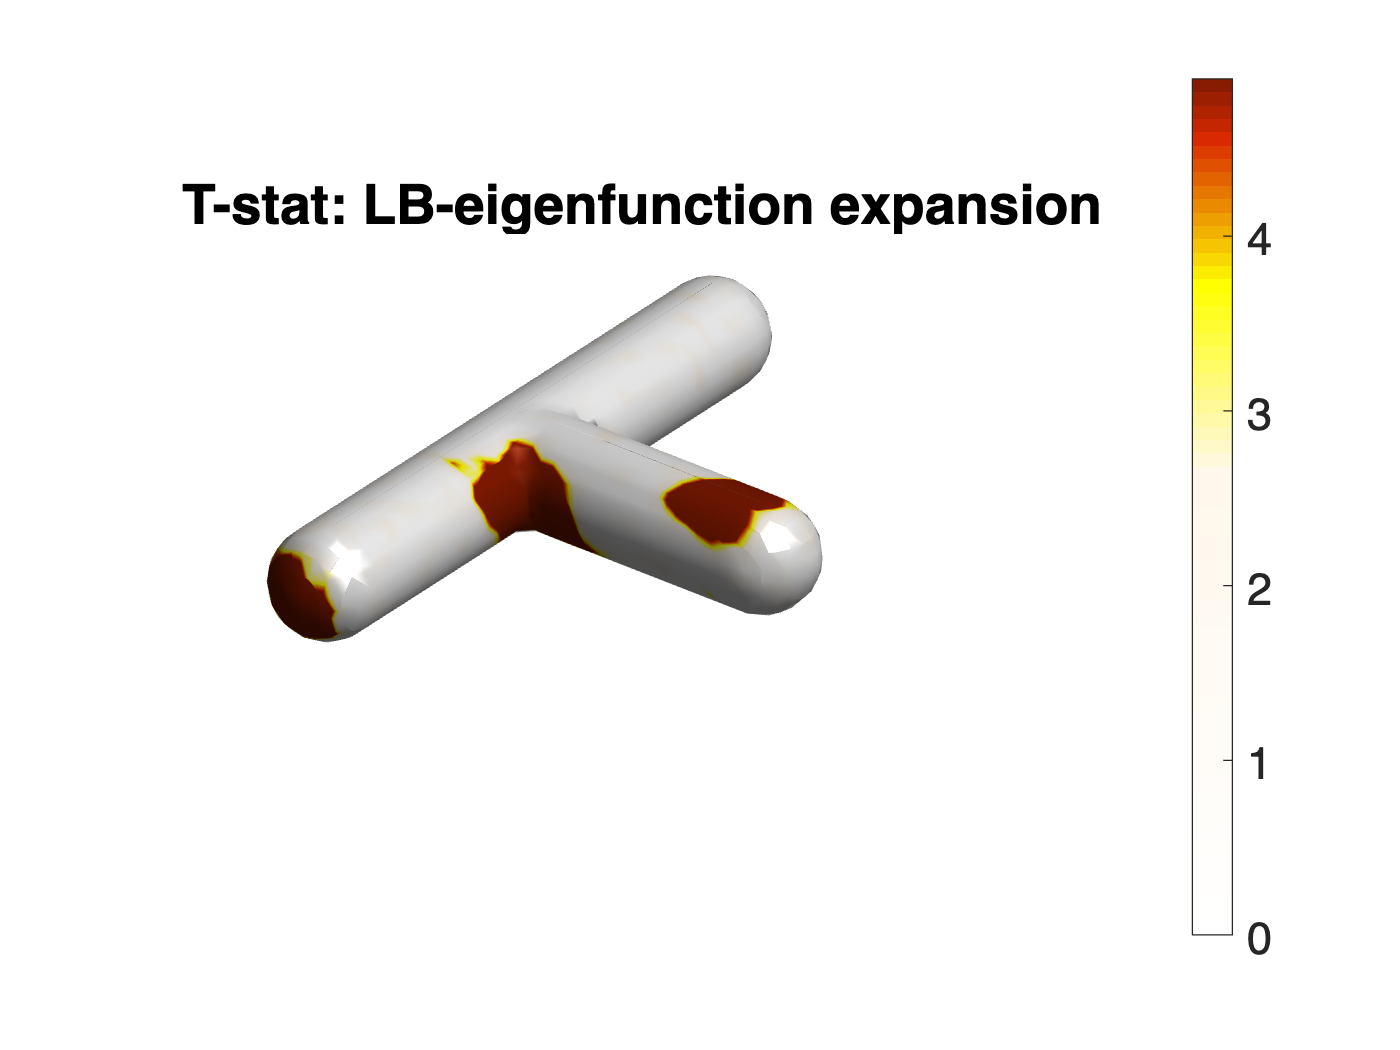

% T-stat is applied to the Fourier series expansion using LB-eigenfunction
% with 1000 basis and bandwidth =0. See the paper. 

[A, C]= FEM(tt); 
[V, D]= eigs(C,A, 1000,'sa');  
msmooth=lb_smooth(measure',tt, 0, 1000, V, D);

mresults1=msmooth(:,1:30);
mresults2=msmooth(:,31:60);

tfield=[];
for i=1:nv
[h p, ci, t] = ttest2(mresults2(i,:), mresults1(i,:),[],[],'equal');
tfield=[tfield t.tstat];
end;

figure; figure_surf(tt, tfield, 'ryw'); colorbar
view([128 30])
material metal
camlight; camlight
figure_bigger(20)
title('T-stat: LB-eigenfunction expansion')
caxis([0 thd])



overlap1 = find(tfield(ROI)>=thd);
length(overlap1)/length(ROI)

ans = 0.1331

% Only able to detect signal up to 30% in area1, area2, area3  
overlap1 = find(tfield(ROIN)>=thd);
length(overlap1)/length(ROIN)

ans = 0

% At least the method is not producing false positives. 


## Heat Kernel Smoothing using Finte Elment Method (FEM) based heat diffusion

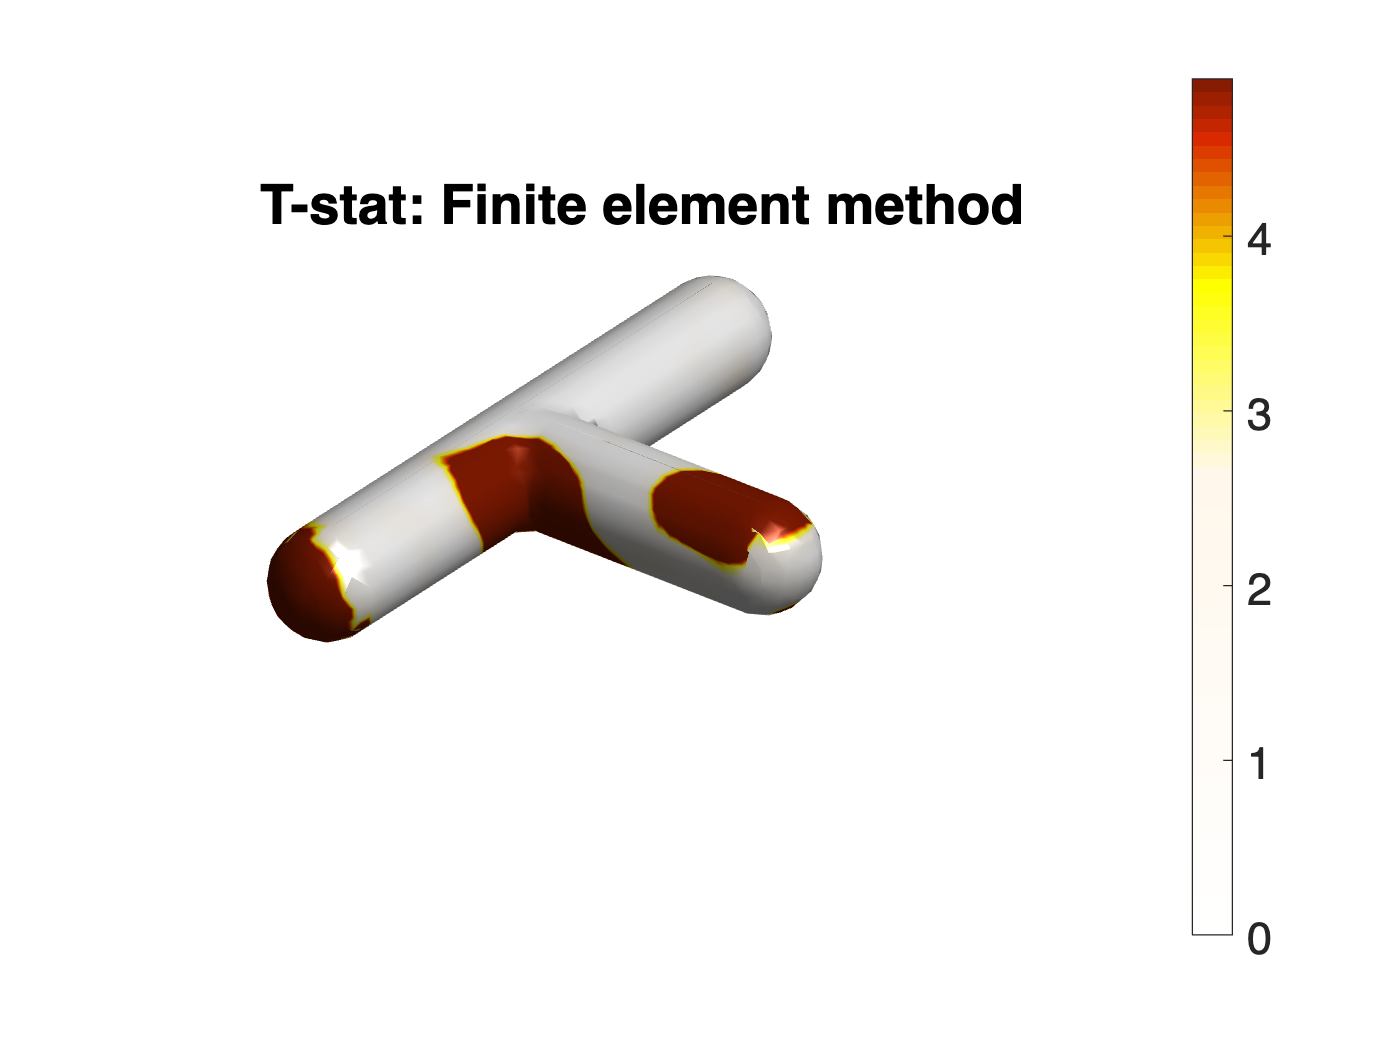

% Heat kernel smoothing (heat diffusion) is equivalent to the LB-eigenfunction
% with addtional exponential weight, which attentuate the high frequcny noise.
% See the paper

output=[];
for i=1:60

    input = measure(i,:);
    dsmooth = diffusion_smooth3(input', tt, 0.5, A,C);
    output(i,:)=dsmooth;
end;

output1=output(1:30,:);
output2=output(31:60,:);

tfield=[];
for i=1:nv
[h p, ci, t] = ttest2(output2(:,i), output1(:,i),[],[],'equal');
tfield=[tfield t.tstat];
end;

figure; figure_surf(tt, tfield, 'ryw'); colorbar
view([128 30])
material metal
camlight; camlight
figure_bigger(20)
title('T-stat: Finite element method')
caxis([0 thd])


overlap1 = find(tfield(ROI)>=thd);
length(overlap1)/length(ROI)

ans = 0.2994

% Should be able to recover about 85%-90% of signal. 
% The false negative error rate is around 100-85% or 100-90% = 10%-15%. 
overlap1 = find(tfield(ROIN)>=thd);
length(overlap1)/length(ROIN)

ans = 0.0031

% False positve error rate shoudl be 1% or less.


